% 假设 M, K, r 已定义，r 是激励方向向量
r0=[1,1,1,0,0,0,0,0,0]';
r = r0;
index1 = [1,7];
index2 = [4,2,3,5,6,8,9];
%r=[1,0,0,1,0,0,1,0,0,1,0,0,1,0,0,1,0,0]';
order = [index1,index2];
K = KPrt(order,order);
M = MPrt(order,order);
[phi, omega2] = eig(K, M);   % 计算模态
omega = sqrt(diag(omega2))

omega =   198.4629
  218.5039
  232.4736
  250.4716
  255.8917
  283.2209
  325.8673
  336.6420
  367.9272



n = size(phi, 2);
Gamma = zeros(n, 1);

for i = 1:n
    phi(:,i) = phi(:,i) / sqrt(phi(:,i)' * M * phi(:,i));  % 质量归一化
    Gamma(i) = phi(:,i)' * M * r;   % 模态参与因子
end

% 可视化参与因子或其平方
GammaSq = Gamma.^2;
participation_ratio = GammaSq / sum(GammaSq)

participation_ratio =     0.0002
    0.0014
    0.0902
    0.0072
    0.5055
    0.3948
    0.0007
    0.0000
    0.0001


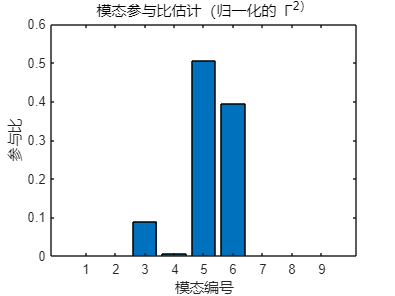

bar(participation_ratio);
xlabel('模态编号');
ylabel('参与比');
title('模态参与比估计（归一化的 Γ^2）');

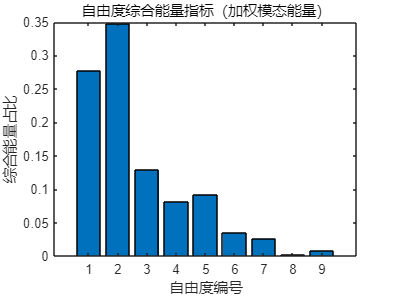


% 假设 phi 是 15自由度 x n模态的矩阵，M 是 15x15的质量矩阵
m = diag(M); % 取对角元素作为等效质量

n_dof = length(m);
n_modes = size(phi, 2);

% 计算角频率 omega_i
omega = sqrt(diag(omega2));  % omega2为广义特征值矩阵

% 初始化自由度-模态能量矩阵
E = zeros(n_dof, n_modes);

for i = 1:n_modes
    for j = 1:n_dof
        E(j,i) = 0.5 * omega(i)^2 * m(j) * phi(j,i)^2;
    end
    E(:,i) = E(:,i) / sum(E(:,i));
    % 对每个模态归一化
end

% E(:,i) 就是模态 i 下各自由度的能量分布比例

% 假设:
% E 是 n_dof x n_modes 的自由度-模态能量矩阵（每列归一化过）
% participation_ratio 是 n_modes x 1 的模态能量占比，且和为1

E_total = E * participation_ratio;  % n_dof x 1，综合能量指标
% 可视化
bar(E_total)
xlabel('自由度编号')
ylabel('综合能量占比')
title('自由度综合能量指标（加权模态能量）')

guyan能量

% 假设 M, K, r 已定义，r 是激励方向向量
r=TP' *r0;
%r=[1,0,0,1,0,0,1,0,0,1,0,0,1,0,0,1,0,0]';
K = KPren;
M = MPren;
[phi, omega2] = eig(K, M);   % 计算模态
omega = sqrt(diag(omega2))

omega =   283.7430
  264.0007



n = size(phi, 2);
Gamma = zeros(n, 1);

for i = 1:n
    phi(:,i) = phi(:,i) / sqrt(phi(:,i)' * M * phi(:,i));  % 质量归一化
    Gamma(i) = phi(:,i)' * M * r;   % 模态参与因子
end

% 可视化参与因子或其平方
GammaSq = Gamma.^2;
participation_ratio = GammaSq / sum(GammaSq)

participation_ratio =     0.3771
    0.6229


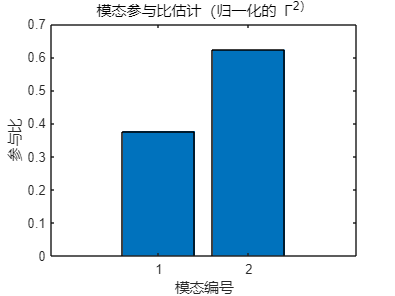

bar(participation_ratio);
xlabel('模态编号');
ylabel('参与比');
title('模态参与比估计（归一化的 Γ^2）');

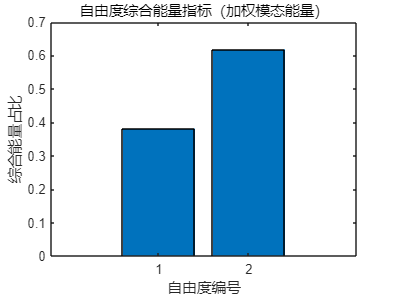


% 假设 phi 是 15自由度 x n模态的矩阵，M 是 15x15的质量矩阵
m = diag(M); % 取对角元素作为等效质量

n_dof = length(m);
n_modes = size(phi, 2);

% 计算角频率 omega_i
omega = sqrt(diag(omega2));  % omega2为广义特征值矩阵

% 初始化自由度-模态能量矩阵
E = zeros(n_dof, n_modes);

for i = 1:n_modes
    for j = 1:n_dof
        E(j,i) = 0.5 * omega(i)^2 * m(j) * phi(j,i)^2;
    end
    % 对每个模态归一化
    E(:,i) = E(:,i) / sum(E(:,i));
end

% E(:,i) 就是模态 i 下各自由度的能量分布比例

% 假设:
% E 是 n_dof x n_modes 的自由度-模态能量矩阵（每列归一化过）
% participation_ratio 是 n_modes x 1 的模态能量占比，且和为1

E_total_guyan = E * participation_ratio;  % n_dof x 1，综合能量指标

% 可视化
bar(E_total_guyan)
xlabel('自由度编号')
ylabel('综合能量占比')
title('自由度综合能量指标（加权模态能量）')


d = [1,2];  % 缩聚前对应自由度索引
E_total_guyan_scalar = sum(sum(E_total_guyan .* participation_ratio')) % Guyan 缩聚系统总能量

E_total_guyan_scalar = 1

increase_rate = (E_total_guyan - E_total(d)) ./ E_total(d) * 100;

% 显示结果
for k = 1:length(d)
    fprintf('自由度 %d -> 缩聚后自由度 %d, 能量占比增加率: %.2f%%\n', d(k), k, increase_rate(k));
end

自由度 1 -> 缩聚后自由度 1, 能量占比增加率: 37.68%
自由度 2 -> 缩聚后自由度 2, 能量占比增加率: 77.52%


cb能量

% 假设 M, K, r 已定义，r 是激励方向向量
r=TP_cb' *r0;
%r=[1,0,0,1,0,0,1,0,0,1,0,0,1,0,0,1,0,0]';
K = KP_cb;
M = MP_cb;
[phi, omega2] = eig(K, M);   % 计算模态
omega = sqrt(diag(omega2))

omega =   287.7062
  262.6866
  198.4881
  233.0205
  218.7136


n = size(phi, 2);
Gamma = zeros(n, 1);

for i = 1:n
    phi(:,i) = phi(:,i) / sqrt(phi(:,i)' * M * phi(:,i));  % 质量归一化
    Gamma(i) = phi(:,i)' * M * r;   % 模态参与因子
end

% 可视化参与因子或其平方
GammaSq = Gamma.^2;
participation_ratio = GammaSq / sum(GammaSq)

participation_ratio =     0.3220
    0.5393
    0.0399
    0.0126
    0.0862


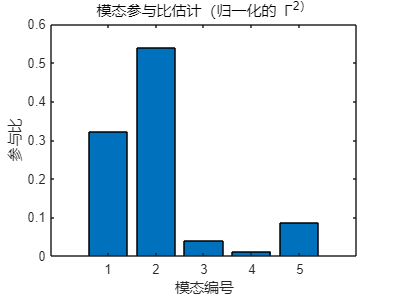

bar(participation_ratio);
xlabel('模态编号');
ylabel('参与比');
title('模态参与比估计（归一化的 Γ^2）');

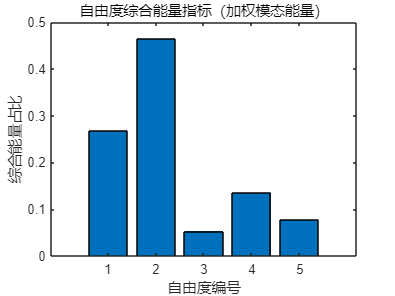


% 假设 phi 是 15自由度 x n模态的矩阵，M 是 15x15的质量矩阵
m = diag(M); % 取对角元素作为等效质量

n_dof = length(m);
n_modes = size(phi, 2);

% 计算角频率 omega_i
omega = sqrt(diag(omega2));  % omega2为广义特征值矩阵

% 初始化自由度-模态能量矩阵
E = zeros(n_dof, n_modes);

for i = 1:n_modes
    for j = 1:n_dof
        E(j,i) = 0.5 * omega(i)^2 * m(j) * phi(j,i)^2;
    end
    % 对每个模态归一化
    E(:,i) = E(:,i) / sum(E(:,i));
end

% E(:,i) 就是模态 i 下各自由度的能量分布比例

% 假设:
% E 是 n_dof x n_modes 的自由度-模态能量矩阵（每列归一化过）
% participation_ratio 是 n_modes x 1 的模态能量占比，且和为1
d2 = d;

E_total_cb = E * participation_ratio;  % n_dof x 1，综合能量指标
increase_rate = (E_total_cb(d2) - E_total(d)) ./ E_total(d) * 100;

% 可视化
bar(E_total_cb)
xlabel('自由度编号')
ylabel('综合能量占比')
title('自由度综合能量指标（加权模态能量）')


% 显示结果
for k = 1:length(d)
    fprintf('自由度 %d -> 缩聚后自由度 %d, 能量占比增加率: %.2f%%\n', d(k), k, increase_rate(k));
end

自由度 1 -> 缩聚后自由度 1, 能量占比增加率: -3.39%
自由度 2 -> 缩聚后自由度 2, 能量占比增加率: 33.16%


总能量

energy_sum_guyan = sum(E_total_guyan);
energy_sum_orig = sum(E_total(d));
total_increase_guyan = (energy_sum_guyan - energy_sum_orig)./ energy_sum_orig * 100

total_increase_guyan = 59.8619


energy_sum_cb = sum(E_total_cb(d2));
energy_sum_orig = sum(E_total(d));
total_increase_cb = (energy_sum_cb - energy_sum_orig)./ energy_sum_orig * 100

total_increase_cb = 16.9607